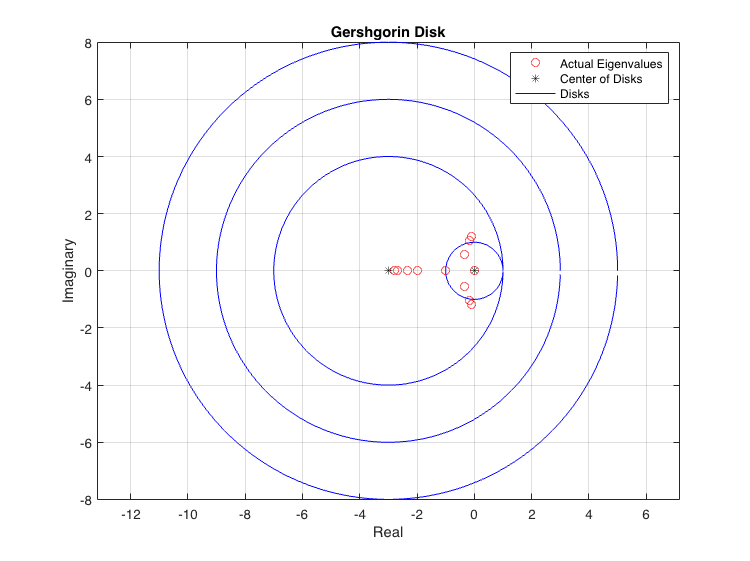


%% state space system

% Adjacency matrix
Adj=[ 0 1 1 1; 1 0 0 0 ; 1 0 0 1; 1 0 1 0];
% Degree matrix
Deg= [ 3 0 0 0; 0 1 0 0 ; 0 0 2 0; 0 0 0 2];
% Laplacian matrix= Degree-Adjacency 
L= Deg-Adj;

I=[1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1];
Y=I;
E=[ 0 1 0; 0 0 1; 0 -2 -3];
F=[ 0 0 0; 0 0 0; 1 0 0 ];
 
O=(kron(I,E))-(kron((Y*L),F));
V=ones(12,1);
W=eye(12);
X=0;
sys=ss(O,V,W,X);

%MohammadReza Jabbari (Jabari) (2021). Gershgorin Disk (https://www.mathworks.com/matlabcentral/fileexchange/72190-gershgorin_disk),
%MATLAB Central File Exchange. Retrieved December 5, 2021.

A=O;

if size(A,1) ~= size(A,2)
error ('Matrix should be square');
return
end
% Gershgorin Disk Theorem
Lambda = eig(A); %Computing true eigenvalues of desired Matrix 'A'
% Obtaining the centers of disks
X = real(diag (A)) ;
Y = imag(diag (A)) ;
% Obtaining the radius of disks
R = sum(abs(A) ,2)-abs(diag(A));
% Plotting Results
% Plot the location of true eigenvalues in real-imaginary coordinate(X axis==real part, Y axis==imaginary part)
plot(real(Lambda),imag(Lambda),'or'); 
hold on
% Plot the centers of disks approximated by Gershgorin Theorem
plot (X, Y, 'k*') ;
% To plot the disks, we use polar coordinate equation of a circle
N= 300;
t = 0:2*pi/N: (2*pi)- (2*pi/N);
X1 = X+R.*repmat (cos(t),size(R, 1),1);
Y1 = Y+R.*repmat(sin(t),size(R,1),1);
plot (X1' ,Y1', 'b-')

axis equal; 
hold off
xlabel ('Real' ); 
ylabel('Imaginary')
title ('Gershgorin Disk')
legend ('Actual Eigenvalues', 'Center of Disks', 'Disks')
grid on